file_m1 = fopen("C:\a_PhD Research\RUL\Codes\HI\m1t1_ta_y.txt", 'r');
data1 = textscan(file_m1, '%f');
fclose(file_m1);

file_m2 = fopen("C:\a_PhD Research\RUL\Codes\HI\m1t2_ta_y.txt", 'r');
data2 = textscan(file_m2, '%f');
fclose(file_m2);

file_m3 = fopen("C:\a_PhD Research\RUL\Codes\HI\m1t3_ta_y.txt", 'r');
data3 = textscan(file_m3, '%f');
fclose(file_m3);

data11 = cell2mat(data1);
healthIndicator11 = data11;

data22 = cell2mat(data2);
healthIndicator22 = data22;

data33 = cell2mat(data3);
healthIndicator33 = data33;

healthIndicator11 = healthIndicator11-min(healthIndicator11);
healthIndicator22 = healthIndicator22-min(healthIndicator22);
healthIndicator33 = healthIndicator33-min(healthIndicator33);

healthIndicator11 = healthIndicator11(11:550);
healthIndicator22 = healthIndicator22(11:550);
healthIndicator33 = healthIndicator33(11:550);

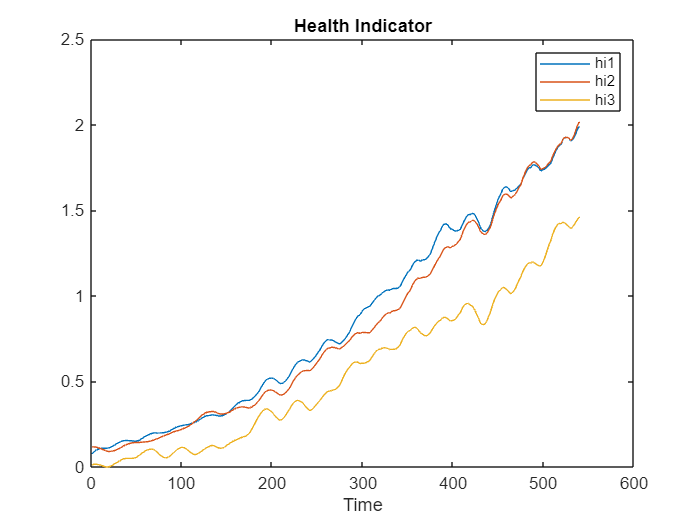

figure
plot(healthIndicator11, 'DisplayName', 'hi1')
hold on;
plot(healthIndicator22, 'DisplayName', 'hi2')
hold on;
plot(healthIndicator33, 'DisplayName', 'hi3')
hold off;
xlabel('Time')
legend
title('Health Indicator')

healthIndicator11

healthIndicator11 =     0.0768
    0.0826
    0.0878
    0.0922
    0.0959
    0.0991
    0.1018
    0.1039
    0.1056
    0.1073


time_idx = [1:1:540]

time_idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


hi22 = table(time_idx', healthIndicator22, 'VariableNames',{'time_indx', 'hi'})

hi22 = 540×2 table
    time_indx       hi   
    _________    ________

        1          0.1174
        2         0.11782
        3         0.11784
        4         0.11741
        5         0.11657
        6         0.11546
        7         0.11406
        8         0.11242
        9         0.11065
       10           0.109
       11         0.10718
       12         0.10498
       13         0.10267
       14         0.10033
       15        0.097969
       16        0.095819


hi33 = table(time_idx', healthIndicator33, 'VariableNames',{'time_indx', 'hi'})

hi33 = 540×2 table
    time_indx       hi    
    _________    _________

        1         0.011876
        2         0.013954
        3         0.015393
        4         0.016149
        5         0.016348
        6         0.016047
        7          0.01534
        8         0.014287
        9         0.012998
       10         0.011743
       11         0.010256
       12        0.0084236
       13        0.0064388
       14         0.004459
       15        0.0025935
       16        0.0010457


tr_hi = {hi22, hi33};
tr_hi = tr_hi';
tr_hi

tr_hi = 2×1 cell array
    {540×2 table}
    {540×2 table}


celldisp(tr_hi(2))

 
ans{1} =
 
    time_indx        hi    
    _________    __________

         1         0.011876
         2         0.013954
         3         0.015393
         4         0.016149
         5         0.016348
         6         0.016047
         7          0.01534
         8         0.014287
         9         0.012998
        10         0.011743
        11         0.010256
        12        0.0084236
        13        0.0064388
        14         0.004459
        15        0.0025935
        16        0.0010457
        17       0.00024602
        18                0
        19       0.00040836
        20        0.0016238
        21         0.003535
        22        0.0059332
        23        0.0087946
        24         0.011864
        25         0.014964
        26         0.018106
        27         0.021226
        28          0.02449
        29         0.027665
        30         0.030551
        31         0.0

%threshold = healthIndicator33(end);
%threshold;

mdl = exponentialDegradationModel('LifeTimeUnit',"seconds")

mdl =   exponentialDegradationModel with properties:

                    Theta: NaN
            ThetaVariance: 1000000
                     Beta: NaN
             BetaVariance: 1000000
                      Rho: 0
      SlopeDetectionLevel: 0.0500
                    Prior: [1×1 struct]
            NoiseVariance: 1
    SlopeDetectionInstant: []
       CurrentMeasurement: 0
                      Phi: 0
     InitialLifeTimeValue: []
     CurrentLifeTimeValue: []
         LifeTimeVariable: ""
             LifeTimeUnit: "seconds"
            DataVariables: [1×0 string]
                 UserData: []
              UseParallel: 0


fit(mdl, tr_hi, "time_indx","hi")
mdl.Prior

ans = struct with fields:
            Theta: 0.3037
    ThetaVariance: 0.0028
             Beta: 0.0036
     BetaVariance: 2.8054e-09
              Rho: 1


mdl.Prior

ans = struct with fields:
            Theta: 0.3037
    ThetaVariance: 0.0028
             Beta: 0.0036
     BetaVariance: 2.8054e-09
              Rho: 1
